# **Parasitology Demo for Image Fundamentals**

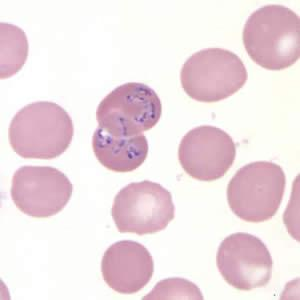

Our analysis will take us through several iterations of basic image processing. The overarching workflow for each iteration will be as follows:

- Access and visualize the image data

- Prototype and develop an image processing algorithm

- Apply the algorithm to the full dataset

*All images used in this demo can be found on the Centers for Disease Control *[*(CDC) DPDx website*](http://www.cdc.gov/dpdx/babesiosis/)*. We gratefully acknowledge the CDC's Division of Parasitic Diseases and Malaria (DPDM). Images are used by permission.*

clear; close all; clc; % gcp;

## Task 1: Accessing and Visualizing the Babesiosis Images

babesiosisDir = fullfile("Labfile_Image",'BloodSmearImages','babesiosis');
imgSet = imageDatastore(babesiosisDir)

imgSet =   ImageDatastore with properties:

                       Files: {
                              ' ...\Labfile_Image\BloodSmearImages\babesiosis\B_MO1_thin_giemsa3.jpg';
                              ' ...\Labfile_Image\BloodSmearImages\babesiosis\B_MO1_thin_giemsa4.jpg';
                              ' ...\Labfile_Image\BloodSmearImages\babesiosis\B_MO1_thin_giemsa5.jpg'
                               ... and 13 more
                              }
                     Folders: {
                              ' ...\Labfile_Image\BloodSmearImages\babesiosis'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage

Datastores are viewed as objects in MATLAB and contain properties and methods. 

properties(imgSet)

Properties for class matlab.io.datastore.ImageDatastore:
    Files
    Folders
    AlternateFileSystemRoots
    ReadSize
    Labels
    SupportedOutputFormats
    DefaultOutputFormat
    ReadFcn


methods(imgSet)


Methods for class matlab.io.datastore.ImageDatastore:

ImageDatastore   combine          copy             countEachLabel   hasdata          isPartitionable  isShuffleable    isSubsettable    numpartitions    partition        preview          read             readall          readimage        reset            shuffle          splitEachLabel   subset           transform        writeall         

Methods of matlab.io.datastore.ImageDatastore inherited from handle.



Let's try using the `readimage` method of imageDatastore to read and visualize an image from the dataset. 

To help us choose an image we can quickly browse the images in the data set using the [**Image Browser App**](matlab:imageBrowser(imgSet)), which can be found in the **Apps** tab.

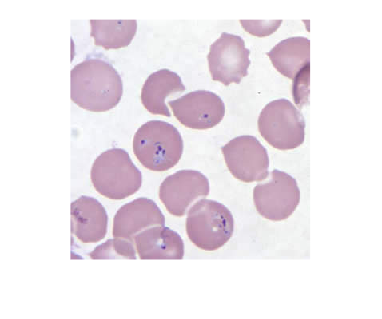

imnum = 4;
targetImage = readimage(imgSet,imnum);
imshow(targetImage)

## Task 2: **Thresholding for a First Pass Cell Mask**

- [Color Thresholder App](matlab:doc('colorThresholder'))

Select the [**Color Thresholder App**](matlab:colorThresholder(targetImage)) from the **Apps** tab and try to pull out the cells from the background. Once you are satisfied, you can generate the code to begin building up your own automated image processing algorithm.

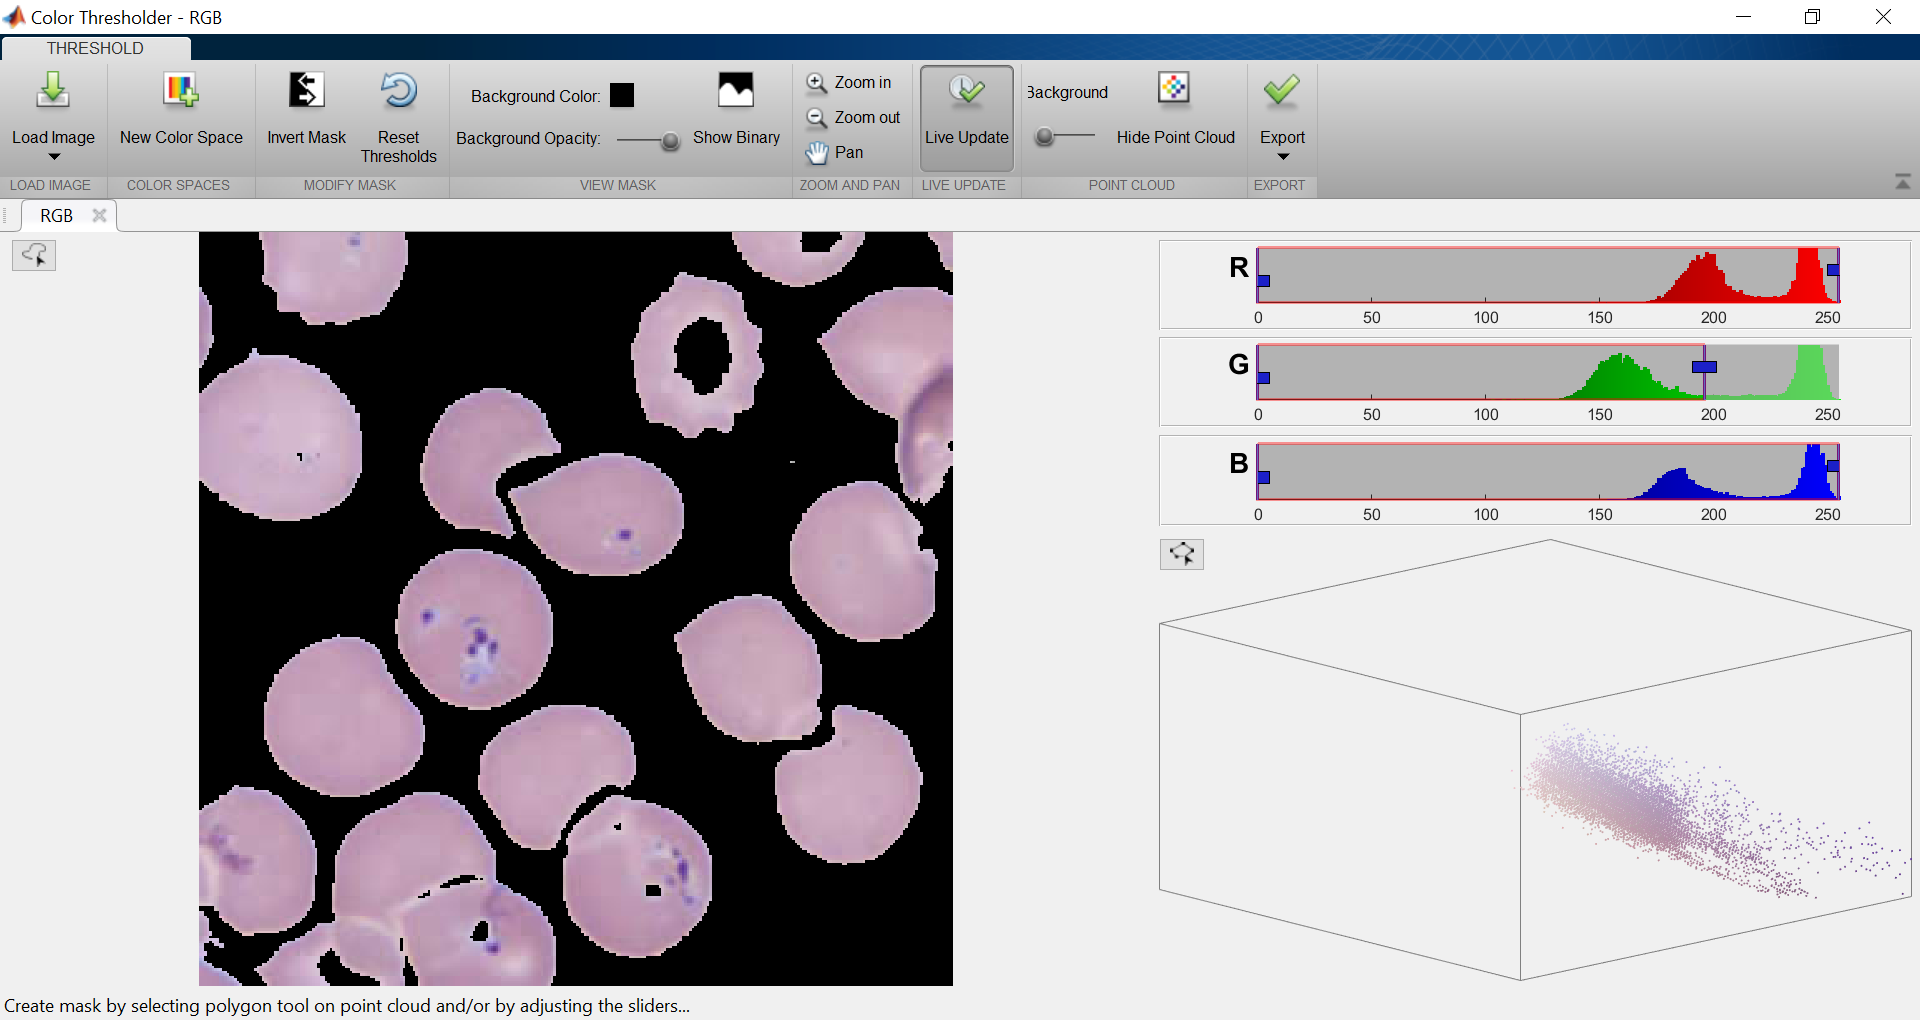

colorThresholder

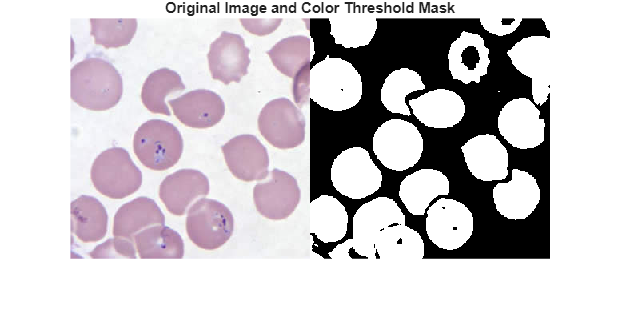

cellMask = createMask(targetImage);
clf; imshowpair(targetImage,cellMask,'montage')
title("Original Image and Color Threshold Mask")

## Task 3: **Filtering and Analyzing Mask Regions**

- [Image Region Analyzer App](matlab:doc('imageRegionAnalyzer'))

Now that we have our cells segmented, we can clean up on our cell mask and examine cell properties using the [**Image Region Analyzer App**](matlab:imageRegionAnalyzer(cellMask)). Try it out until you are satisfied and then generate the code for our algorithm.

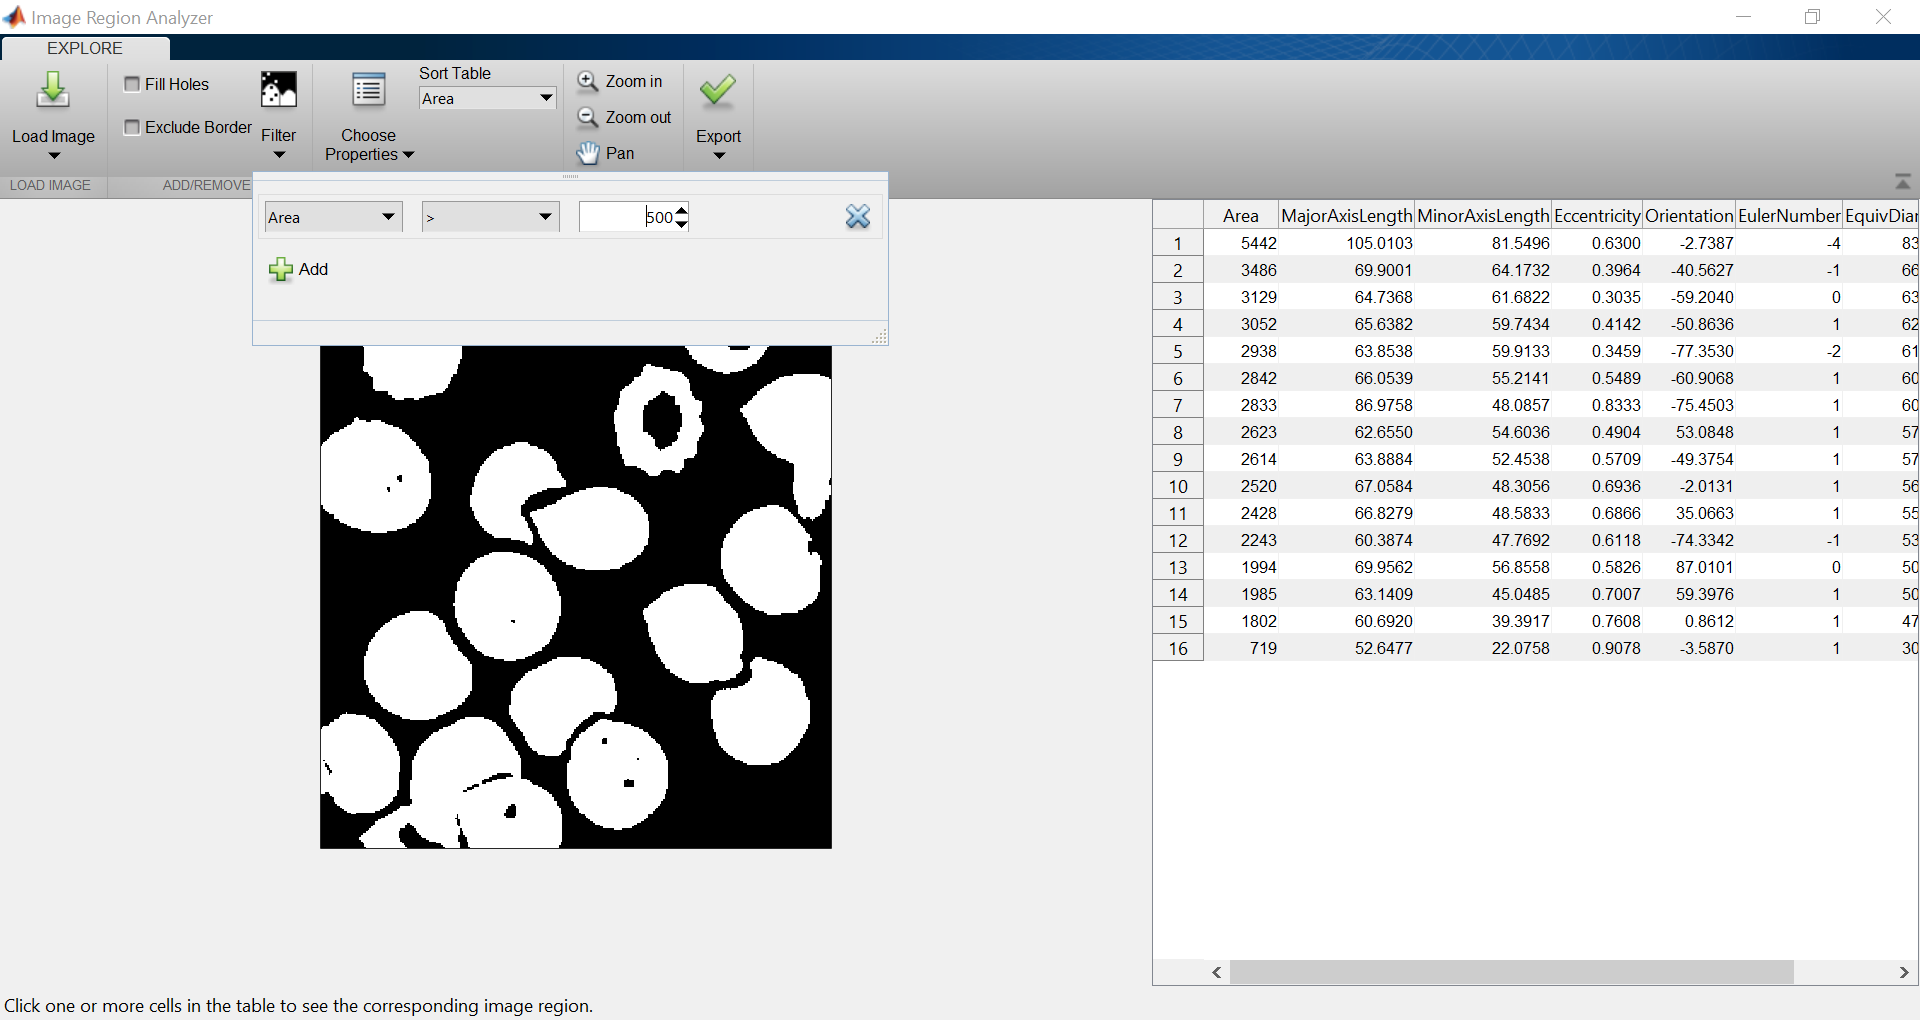

imageRegionAnalyzer

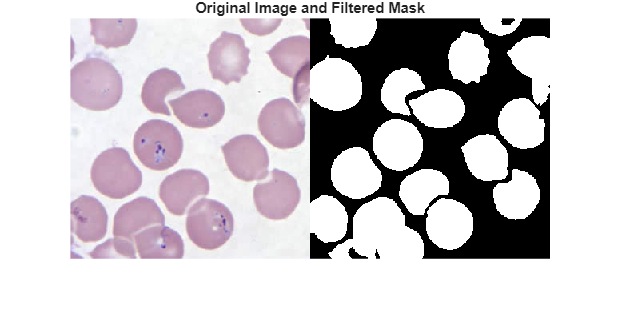

[cellMask, props] = filterRegions(cellMask);
clf; imshowpair(targetImage,cellMask,'montage')
title("Original Image and Filtered Mask")

The `propsTable` output is a table of the region properties computed in the **Image Region Analyzer**. Explore the props table and try creating visualizations from this variable using the **Variable Editor** and the **Plots** tab.

propsTable

propsTable = 16×8 table
    Area    Eccentricity    EquivDiameter    EulerNumber    MajorAxisLength    MinorAxisLength    Orientation    Perimeter
    ____    ____________    _____________    ___________    _______________    _______________    ___________    _________
    3522      0.39194          66.965             1             69.948             64.351           -41.282        215.8  
    2269      0.60386          53.749             1             60.368             48.119           -74.735       173.47  
    5599      0.63354          84.433             1             104.83             81.107            -1.601       375.26  
    1810      0.75889          48.006             1             60.743             39.557

## **Task 4: Using Edge Detection to Segment Overlapping Cells**

Let's try seperating these cells by finding the cell edges.

we can try using the [`edge`](matlab:doc('edge')) function.

or by using an interactive app such as the [**SegmentImage**](matlab:matlab.apputil.run('segmentImage')) from the image processing community on the MATLAB [File Exchange](https://www.mathworks.com/matlabcentral/fileexchange/38484-segmenttool-an-interactive-gui-for-segmenting-images).

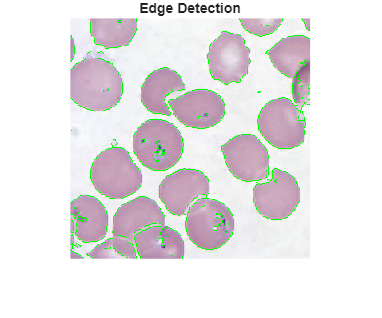

grayscale = rgb2gray(targetImage);
edges = edge(grayscale,'Sobel',0.03,'Both');
clf; imshow(imoverlay(targetImage,edges,'green'))
title("Edge Detection")

Notice that the detected edges are not always contiguous. We'll try using morphological operations to close these breaks in the cell edges.

Morphological *closing* of an image ([`imclose`](matlab:doc('imclose'))) consists of dilation ([`imdilate`](matlab:doc('imdilate'))) followed by erosion ([`imerode`](matlab:doc('imerode'))) with the same structuring element ([`strel`](matlab:doc('strel'))) for both operations.The related operation, morphological *opening* of an image ([`imopen`](matlab:doc('imopen'))), is the reverse

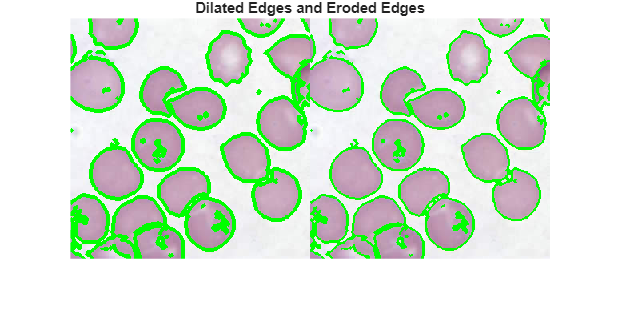

dedge = imdilate(edges,strel('Disk',2));
edges = imerode(dedge,strel('Disk',1));
clf; imshowpair(imoverlay(targetImage,dedge,'green'), ...
  imoverlay(targetImage,edges,'green'),'montage')
title("Dilated Edges and Eroded Edges")

Once satisfied with our edge detection, we'll combine this result with our previous threshold mask. Notice the cleaner separation between overlapping cells.

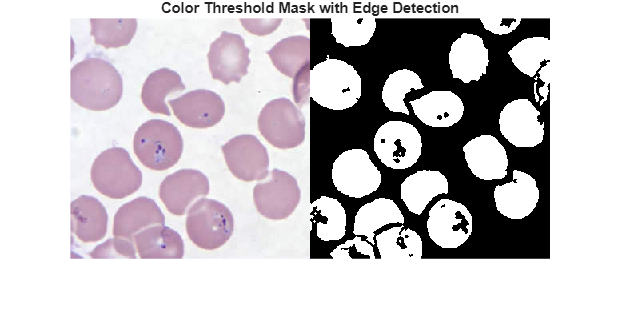

cellMask(edges==1) = 0;
clf; imshowpair(targetImage,cellMask,'montage')
title("Color Threshold Mask with Edge Detection")

#### Alternative 2: Finding Circles

Consider treating the red blood cells as circles. Use the [**Image Segmenter App**](matlab:imageSegmenter(targetImage)) to find circles with a range of diameter lengths.

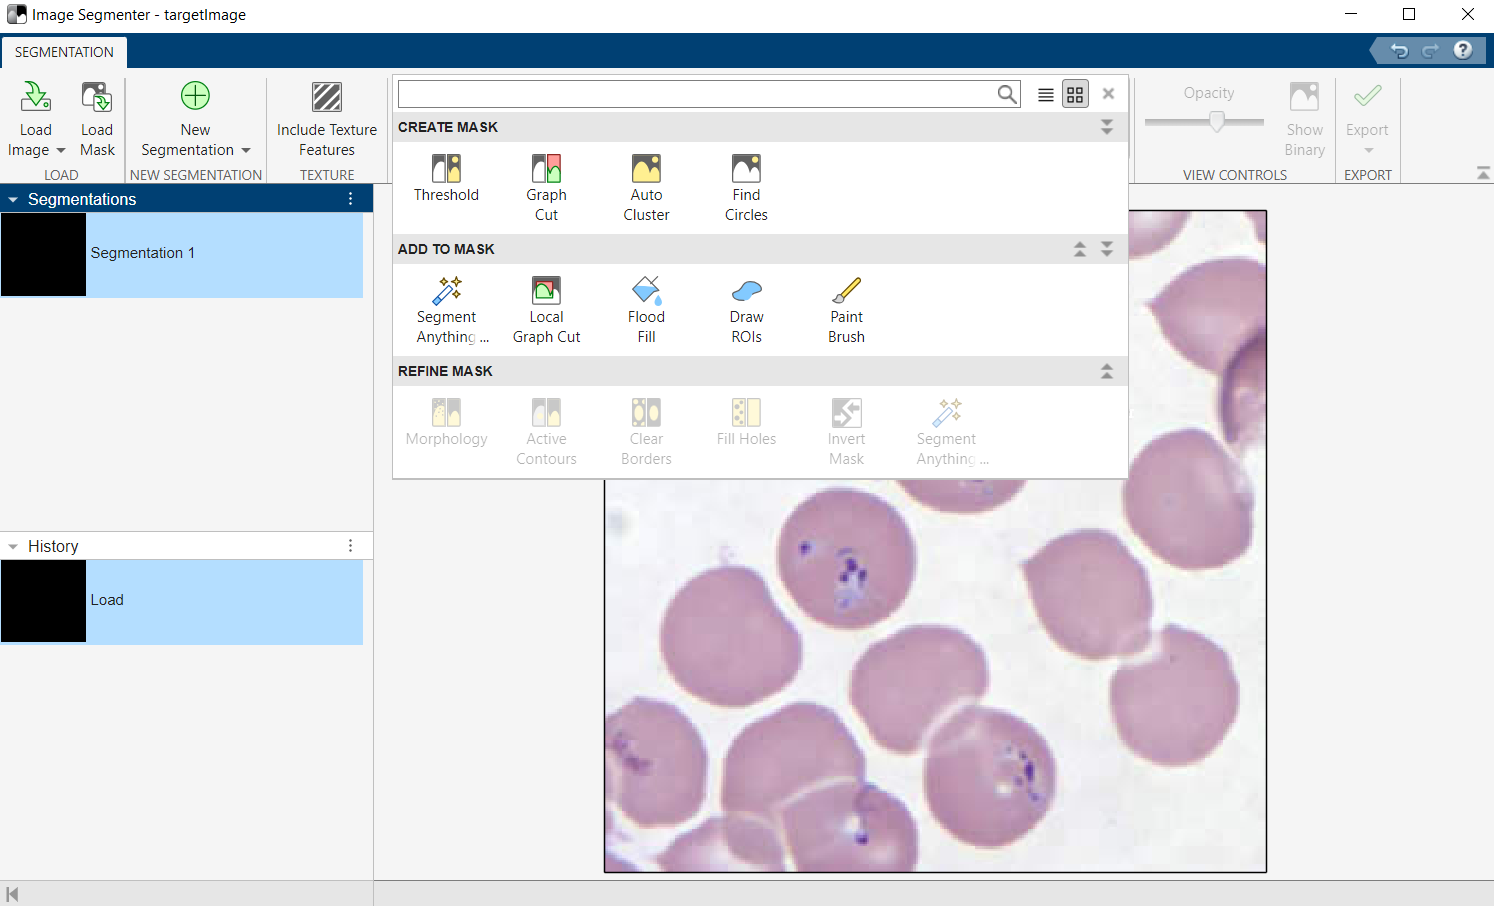

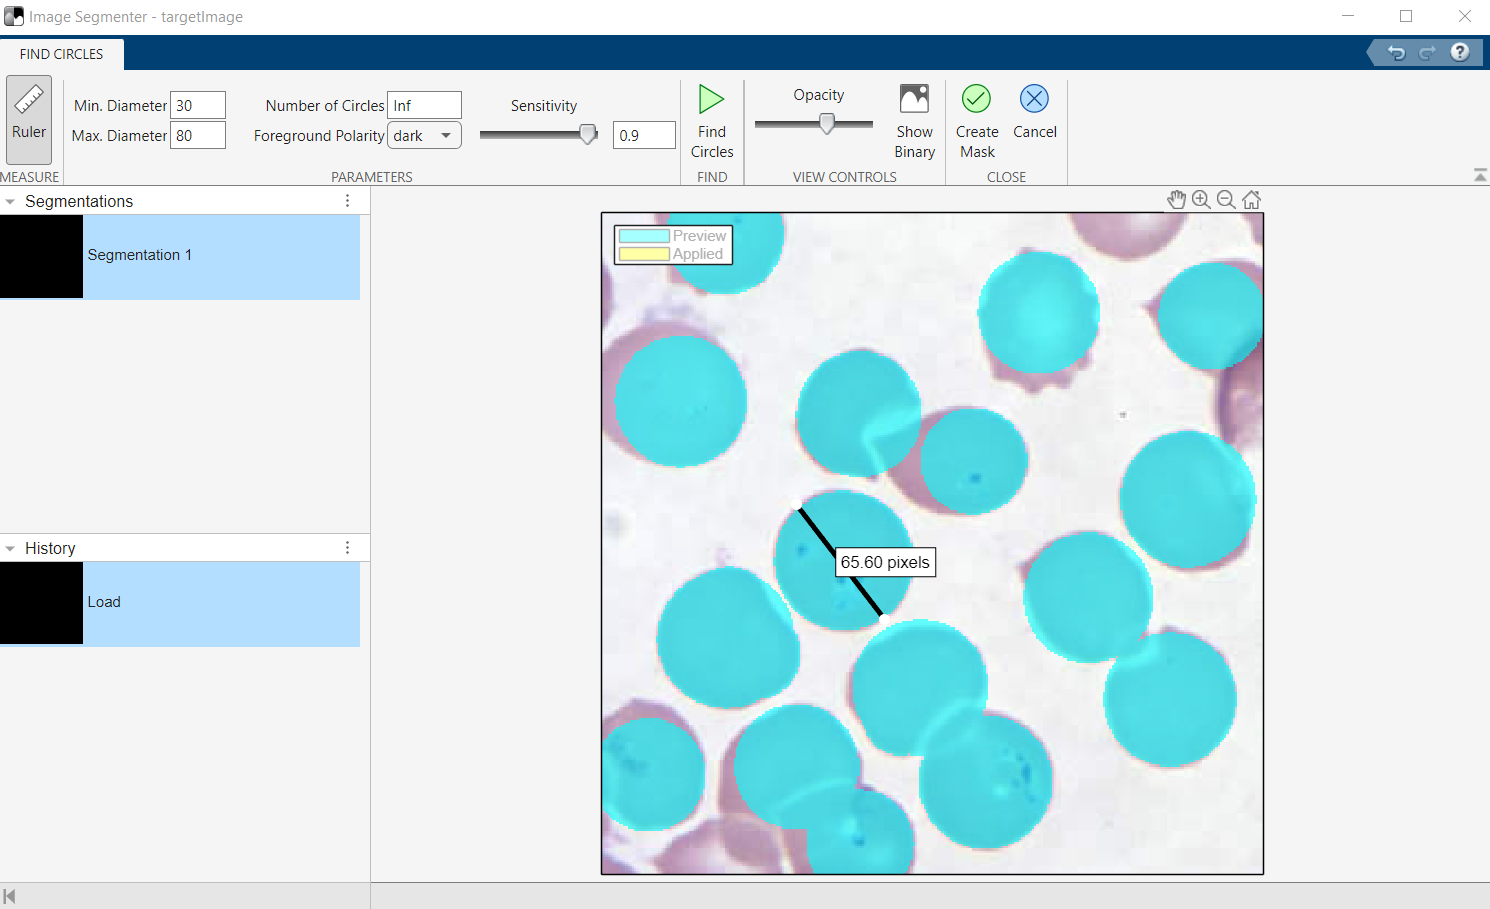

imageSegmenter(targetImage)

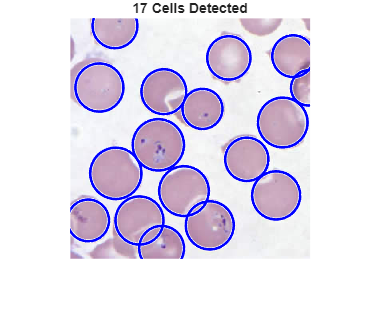

% Copied from auto-generated code from Image Segmenter App
[centers,radii,~] = imfindcircles(targetImage,[20 35],'Sensitivity',0.89,'EdgeThreshold',0.04,'Method','TwoStage','ObjectPolarity','Dark');

clf; imshow(targetImage)
viscircles(centers,radii,'Color','b');
title(numel(radii) + " Cells Detected")

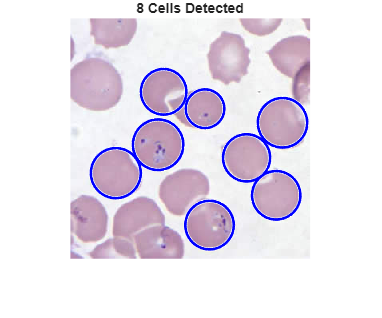

% Find circles
[centers,radii,~] = imfindcircles(targetImage,[15 40],'ObjectPolarity','dark','Sensitivity',0.85);
% max_num_circles = Inf;
% if max_num_circles < length(radii)
%     centers = centers(1:max_num_circles,:);
%     radii = radii(1:max_num_circles);
% end
% BW = circles2mask(centers,radii,size(targetImage,1:2));
% % Create masked image.
% maskedImage = targetImage;
% maskedImage(repmat(~BW,[1 1 3])) = 0;

clf; imshow(targetImage)
viscircles(centers,radii,'Color','b');
title(numel(radii) + " Cells Detected")

## Task 5: Automating Image Processing

The two automatically generated MATLAB functions combined with our edge detection mask make up our preliminary image processing algorithm for segmenting the blood cells from the image.

Let's automate the analysis of the images with this algorithm using the [**Image Batch Processor App**](matlab:imageBatchProcessor) to examine how well our algorithm performs on the other images.